clc; clear; close all;

# **Computing PALF Week 4**

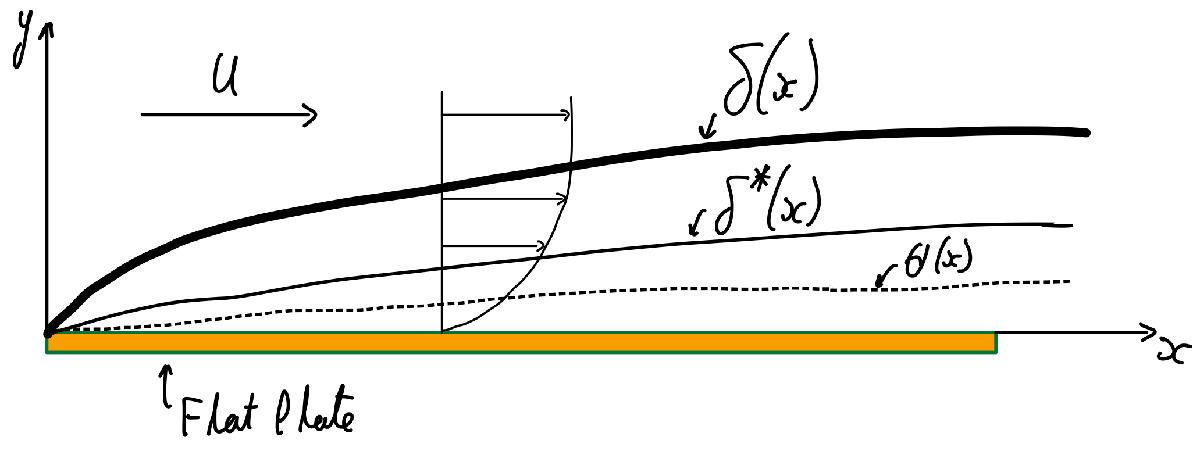

**Reynolds number with respect to the x direction**


$$Re_{x} = \frac{\rho u x}{\mu}, \ \text{where } \rho=1.225\ kg/m^{3}, \ u=20\ m/s, \ \mu=1.81e-5\ Pas$$


**Laminar and turbulent boundary layer thickness:**


$$\frac{\delta}{x}_{l} = \left(\frac{30}{Re_{x}} \right) ^{0.5} \ , \ \frac{\delta}{x}_{t} = \frac{0.38}{Re_{x}^{0.2}}$$


**Displacement thickness:**


$$\frac{\delta^*}{x} = \frac{1.721}{Re_{x}^{0.5}}$$


**Momentum thickness:**


$$\frac{\theta}{x} = \frac{0.664}{Re_{x}^{0.5}}$$


**Laminar and turbulent skin friction coefficient:**


$$C_{fl} = \left( \frac{8}{15 * Re_{x}} \right)^{0.5} \ , \ C_{ft} = \frac{0.03}{Re_{x}^{0.2}}$$


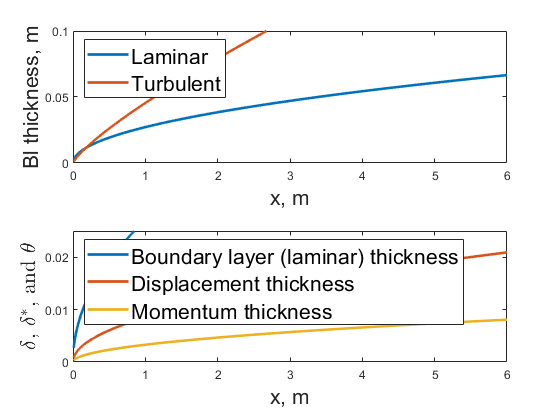

clc; clear; close all;
% Constants and Reynolds number
x_end = 6; % End x position of plate
rho = 1.225; % Density, kg/m^3
u = 60; % Freestream velocity, m/s
mu = 1.81e-3; % Dynamic viscosity, Pas
x = [0:0.01:x_end]; % x-position, m
re_x = rho * u * x / mu; % Reynolds number varying with x

% Empirically derived thickness equations 
delta_l = x .* sqrt(30./re_x); % Laminar bounday layer thickness
delta_t = x .* 0.38 ./ (re_x.^0.2); % Turbulent boundary layer thickness
delta_star = x .* 1.721 ./ (re_x .^0.5); % Displacement thickness
theta = x .* 0.664 ./ (re_x.^0.5); % Momentum thickness
C_f_l = sqrt(8./(15 * re_x)); % Laminar skin friction coefficient
C_f_t = 2 * 0.03 ./ (re_x.^0.2); % Turbulent skin friction coefficient

figure;
subplot(2,1,1)
plot(x,delta_l, x,delta_t, 'LineWidth',2)
xlabel('x, m', 'FontSize',16); ylabel('Bl thickness, m', 'FontSize',16)
legend('Laminar', 'Turbulent', 'FontSize', 16, 'Location', 'northWest')
ylim([0 0.1])
subplot(2,1,2)
plot(x, delta_l, x, delta_star, x, theta, 'LineWidth',2)
xlabel('x, m', 'FontSize',16); ylabel('$\delta$, $\delta^*$, and $\theta$', 'FontSize',16, 'Interpreter','latex')
legend('Boundary layer (laminar) thickness', 'Displacement thickness', 'Momentum thickness', 'FontSize',16, 'Location', 'northWest')
ylim([0 0.025])

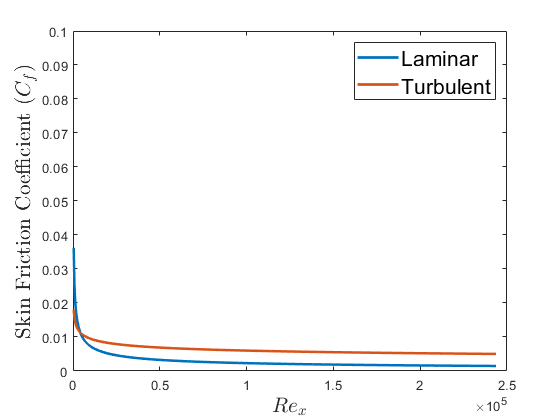


figure;
plot(re_x, C_f_l, re_x, C_f_t, 'LineWidth',2)
xlabel('$Re_x$', 'FontSize',16, 'Interpreter','latex'); ylabel('Skin Friction Coefficient ($C_f$)', 'FontSize',16, 'Interpreter','latex')
legend('Laminar', 'Turbulent', 'FontSize', 16)
ylim([0 0.1])